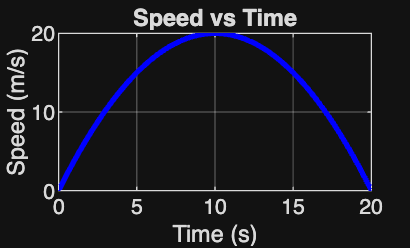

%{
ES115 - Control Panel Class Project
Author: Nivea Williamson
Version: 1.0
Date: 2026-04-20

Purpose:
    Model the speed of an autonomous cart over time, compute its
    acceleration using numerical methods, and analyze when speed
    is maximized.

Input:
    - Time values from 0 to 20 seconds
    - Speed function: v(t) = -0.2(t - 10)^2 + 20

Output:
    - Plot of speed vs time
    - Plot of acceleration vs time
    - Time when speed is maximum
    - Interpretation of acceleration near that time

Engineering Algorithms:
    - Define time vector
    - Compute speed using given quadratic function
    - Plot speed vs time
    - Use finite differences to estimate acceleration
    - Plot acceleration vs time
    - Identify maximum speed and corresponding time

MATLAB Tools/Functions:
    - plot()
    - hold on
    - grid on
    - title()
    - xlabel()
    - ylabel()
    - max()
    - diff()
    - trapz()
%}

%% PROJECT 3

clc;
clear;

% Time vector
t = 0:0.2:20;

% Speed function
v = -0.2*(t - 10).^2 + 20;

%% Plot speed vs time
figure;
plot(t, v, 'b', 'LineWidth', 2)
title('Speed vs Time')
xlabel('Time (s)')
ylabel('Speed (m/s)')
grid on;

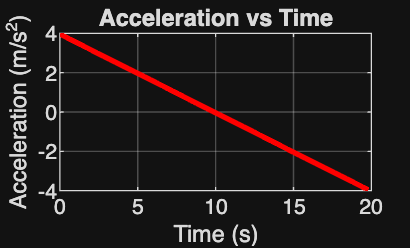


%% Numerical acceleration using finite differences
dt = 0.2;                      % time step
a = diff(v) / dt;              % acceleration approximation
t_a = t(1:end-1);              % match size of acceleration

%% Plot acceleration vs time
figure;
plot(t_a, a, 'r', 'LineWidth', 2)
title('Acceleration vs Time')
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')
grid on;


%% Find maximum speed and time
[max_v, idx] = max(v);
t_max = t(idx);

fprintf('Maximum speed = %.2f m/s at time = %.2f s\n', max_v, t_max);

Maximum speed = 20.00 m/s at time = 10.00 s



%% Optional: Distance using trapezoidal rule
distance = trapz(t, v);
fprintf('Estimated total distance traveled = %.2f meters\n', distance);

Estimated total distance traveled = 266.64 meters
